# run ryan4_model_incremetal_learning_data

% all(ynorm_ref == ynorm_ref_to_small2)

ytrain = ynorm_ref
Xtrain = xnorm_ref
Ytrain = Y_ref

ytrain =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615


Ytrain_soh = Y_soh_ref

Xtrain =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011
    0.9218    0.8783    0.8680    0.8601    0.8523    0.8440    0.8348    0.8250    0.8143    0.8024    0.7881    0.7699    0.7451    0.7080    0.6451    0.5216    0.2288    0.0009    0.0008    0.0008
    0.9217    0.8781    0.8678    0.8599    0.8521    0.8438    0.8346    0.8247    0.8141    0.8022    0.7878    0.7697    0.7448    0.7076    0.6446    0.5207    0.2269    0.0011    0.0011    0.0011
    0.9221    0.8784    0.8680    0.8602    0.8524    0.8440    0.8349    0.8249    0.8142    0.8023    0.7880    0.7698    0.7449    0.7077    0.6444    0.5201    0.2233    0.0009    0.0009    0.0009
    0.9222    0.8786    0.8682    0.8603    0.8525    0.8441    0.8349    0.8250    0.8143    0.8025    0.7881    0.7699    0.7450    0.7076    0.6442    0.5194    0.2209    0.0010    0.0

Ytrain =    316
   315
   314
   313
   312
   311
   310
   309
   308
   307


n = numel(ytrain);

Ytrain_soh =     1.0477
    1.0476
    1.0474
    1.0473
    1.0471
    1.0470
    1.0468
    1.0467
    1.0465
    1.0464


For details on the data set, enter  `Description` at the command line.

Create an incremental linear model for regression. Configure the model as follows:

- Specify the SGD solver.

- Assume that these settings work well for the problem: a ridge regularization parameter value of 0.001, SGD batch size of 20, learning rate of 0.002, and half the width of the epsilon insensitive band for SVM of 0.05.

- Specify that the incremental fitting functions process the raw (unstandardized) predictor data.

- Specify a metrics warm-up period of 1000 observations.

- Specify a metrics window size of 500 observations.

- Track the epsilon insensitive loss, MSE, and mean absolute error (MAE) to measure the performance of the model. The software supports epsilon insensitive loss and MSE. Create an anonymous function that measures the absolute error of each new observation. Create a structure array containing the name `MeanAbsoluteError` and its corresponding function.

maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);

% Mdl = incrementalRegressionLinear('Epsilon',0.05, ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',1000,'MetricsWindowSize',500, ...
%     'Metrics',{'epsiloninsensitive' 'mse_val' maemetric})

Mdl = incrementalRegressionLinear(  ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.002, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',10, ...
    'Learner','leastsquares', ...
    'Metrics',{ 'mse' })

`Mdl` is an `incrementalRegressionLinear` model object configured for incremental learning without an estimation period.

Fit the incremental model to the data by using the `updateMetricsAndFit` function. At each iteration:

- Simulate a data stream by processing a chunk of 50 observations. Note that the chunk size is different from SGD batch size.

- Overwrite the previous incremental model with a new one fitted to the incoming observations.

- Store the estimated coefficient $\beta_{10}$, the cumulative metrics, and the window metrics to see how they evolve during incremental learning.

% Preallocation
numObsPerChunk = 5; %50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
% mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);

Mdl =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [0×1 double]
                 Bias: 0
              Learner: 'leastsquares'


  Properties, Methods


beta10 = zeros(nchunk,1);    

% Incremental fitting
rng("default"); % For reproducibility
for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend ;    
    Mdl = updateMetricsAndFit(Mdl,Xtrain(idx,:),ytrain(idx));
    Mdl.Beta;
    Mdl.Bias;
    %ei{j,:} = Mdl.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = Mdl.Metrics{"MeanSquaredError",:};
    % mae{j,:} = Mdl.Metrics{"MeanAbsoluteError",:};
    beta10(j + 1) = Mdl.Beta(10);
end

`Mdl` is an `incrementalRegressionLinear` model object trained on all the data in the stream. During incremental learning and after the model is warmed up, `updateMetricsAndFit` checks the performance of the model on the incoming observations, and then fits the model to those observations.

To see how the performance metrics and $\beta_{10}$ evolve during training, plot them on separate tiles.

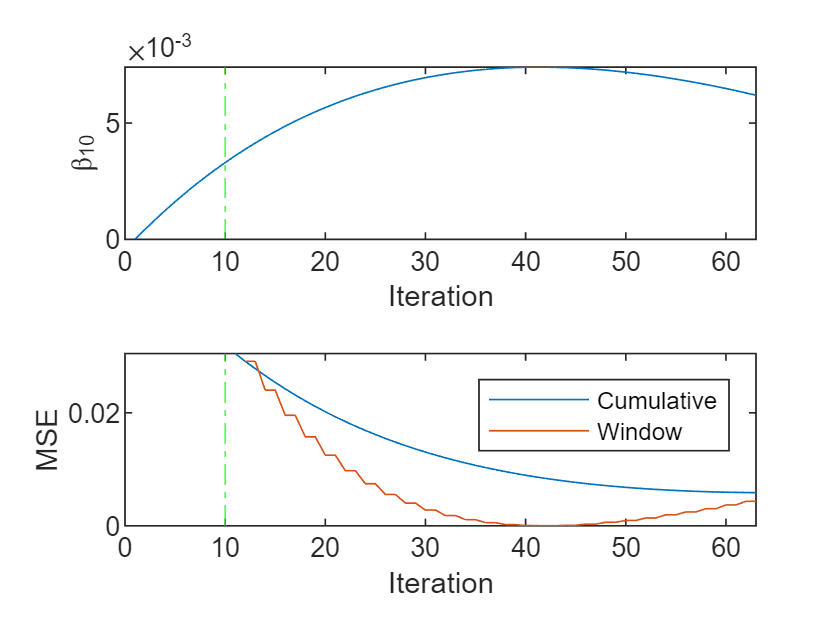

tiledlayout(2,1)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
% nexttile
% h = plot(ei.Variables);
% xlim([0 nchunk])
% ylabel('Epsilon Insensitive Loss')
% xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,ei.Properties.VariableNames)
% xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')

% nexttile
% h = plot(mae.Variables);
% xlim([0 nchunk])
% ylabel('MAE')
% xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,mae.Properties.VariableNames)
% xlabel('Iteration')

The plot suggests that `updateMetricsAndFit` does the following:

- Fit $\beta_{10}$ during all incremental learning iterations.

- Compute the performance metrics after the metrics warm-up period only.

- Compute the cumulative metrics during each iteration.

- Compute the window metrics after processing 500 observations (10 iterations).

*Copyright 2020 The MathWorks, Inc.*

total = length(ytrain)

total = 315

pre = 50;
future = total - pre

future = 265

Xtrain_all = Xtrain ;
ytrain_all = ytrain ;
Ytrain_all = Ytrain ;
Ytrain_SOH_all = Ytrain_soh;

Xtrain_pre = Xtrain(1:pre,:);
ytrain_pre = ytrain(1:pre,:);
Ytrain_pre = Ytrain(1:pre,:);
Ytrain_SOH_pre = Ytrain_soh(1:pre,:);

Xtrain_future = Xtrain(pre+1:end,:);
ytrain_future = ytrain(pre+1:end,:);
Ytrain_future = Ytrain(pre+1:end,:);
Ytrain_SOH_future = Ytrain_soh(pre+1:end,:);

[Mdl1,FitInfo] = fitrlinear(Xtrain_pre,ytrain_pre,"learner","leastsquares")

Mdl1 =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: 0.2473
               Lambda: 0.0200
              Learner: 'leastsquares'


  Properties, Methods


FitInfo = struct with fields:
                    Lambda: 0.0200
                 Objective: 7.4262e-05
            IterationLimit: 1000
             NumIterations: 8
              GradientNorm: 1.6935e-05
         GradientTolerance: 1.0000e-06
      RelativeChangeInBeta: 7.8861e-05
             BetaTolerance: 1.0000e-04
             DeltaGradient: []
    DeltaGradientTolerance: []
           TerminationCode: 1
         TerminationStatus: {'Tolerance on coefficients satisfied.'}
                   History: []
                   FitTime: 4.4860e-04
                    Solver: {'bfgs'}


Mdl1.Beta

ans =    -0.0010
   -0.0008
   -0.0008
   -0.0007
   -0.0007
   -0.0006
   -0.0006
   -0.0006
   -0.0005
   -0.0004


Mdl1.Bias

ans = 0.2473

yhat_pre_calc = Xtrain_pre(1,:) * Mdl1.Beta + Mdl1.Bias

yhat_pre_calc = 0.2488

yhat_pre_predict = predict(Mdl1,Xtrain_pre(1,:))

yhat_pre_predict = 0.2488

# 현재까지 학습된 자신의 모델로 과거값을 예측하면 오차가 작다. 그러나 정확하지는 않다.

yhat_pre = predict(Mdl1,Xtrain_pre);


Yhat_pre = yhat_pre * yrate_RUL + ymin_RUL;

rmse_pre = sqrt( mean((Ytrain_pre - Yhat_pre).^2 ) )

rmse_pre = 14.0912

diff_percentage_pre = abs(Ytrain_pre - Yhat_pre)./Ytrain_pre.*100

diff_percentage_pre =     7.5688
    7.2981
    7.0129
    6.7337
    6.4467
    6.1506
    5.8544
    5.5538
    5.2625
    4.9647


diff_percentage_avg_pre = mean(diff_percentage_pre,1)

diff_percentage_avg_pre = 4.2072

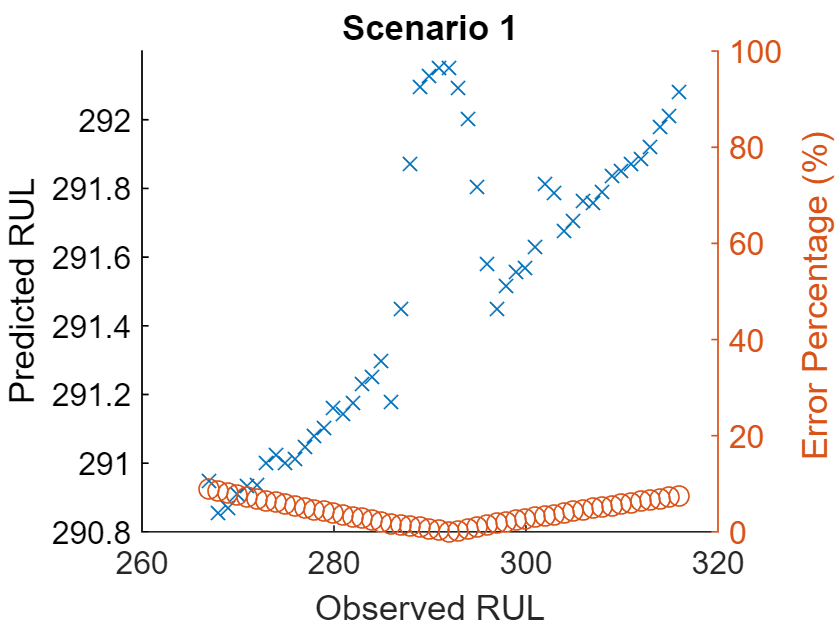

figure
hold on
%plot(Ytrain_pre,Ytrain_pre)
plot(Ytrain_pre,Yhat_pre,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage (%) ')
plot(Ytrain_pre,diff_percentage_pre,'o');
ylim([0 100])

hold off
title 'Scenario 1'

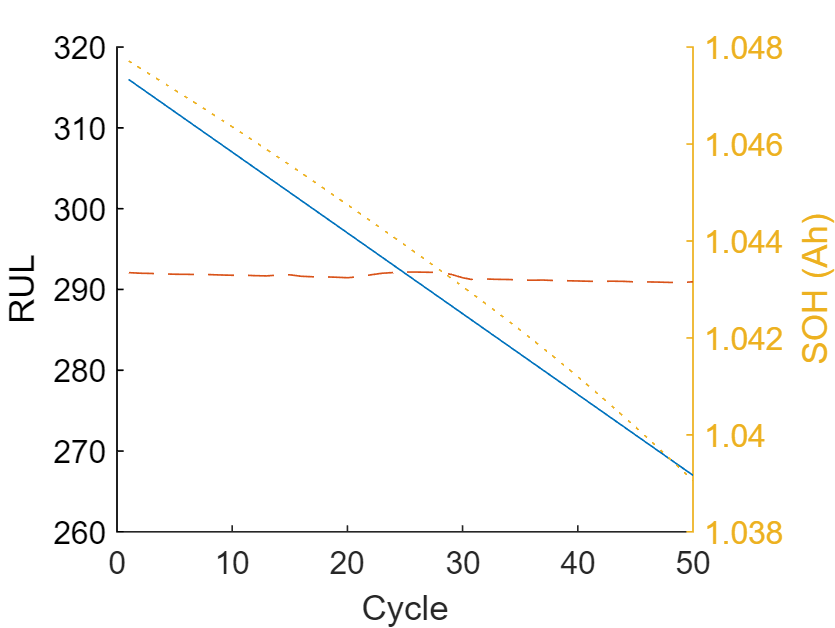

% legend_str = cell(2,1);
% legend_str{1} = 'RUL';
% legend_str{2} = 'Error Percentage (%)';
% legend(legend_str)

figure, hold on
plot(Ytrain_pre)
plot(Yhat_pre,'--')
ylabel('RUL')

yyaxis right
ylabel('SOH (Ah)'), xlabel('Cycle')
plot(Ytrain_SOH_pre, ':')
hold off

% legend_str = cell(3,1);
% legend_str{1} = 'Predicted RUL';
% legend_str{2} = 'Observed RUL';
% legend_str{3} = 'Error Percentage (%)';
% legend(legend_str)

# 현재까지 학습된 자신의 모델로 미래를 예측하면 예측오차가 매우 커진다.

yhat_future = predict(Mdl1,Xtrain_future);
Yhat_future = yhat_future*yrate_RUL + ymin_RUL;
rmse_future = sqrt( mean((Ytrain_future - Yhat_future).^2 ) )

rmse_future = 169.4288

diff_percentage_future = abs(Ytrain_future - Yhat_future)./Ytrain_future.*100

diff_percentage_future = 1.0e+04 *

    0.0009
    0.0010
    0.0010
    0.0011
    0.0011
    0.0012
    0.0012
    0.0012
    0.0013
    0.0013


diff_percentage_avg_future = mean(diff_percentage_future,1)

diff_percentage_avg_future = 454.0499

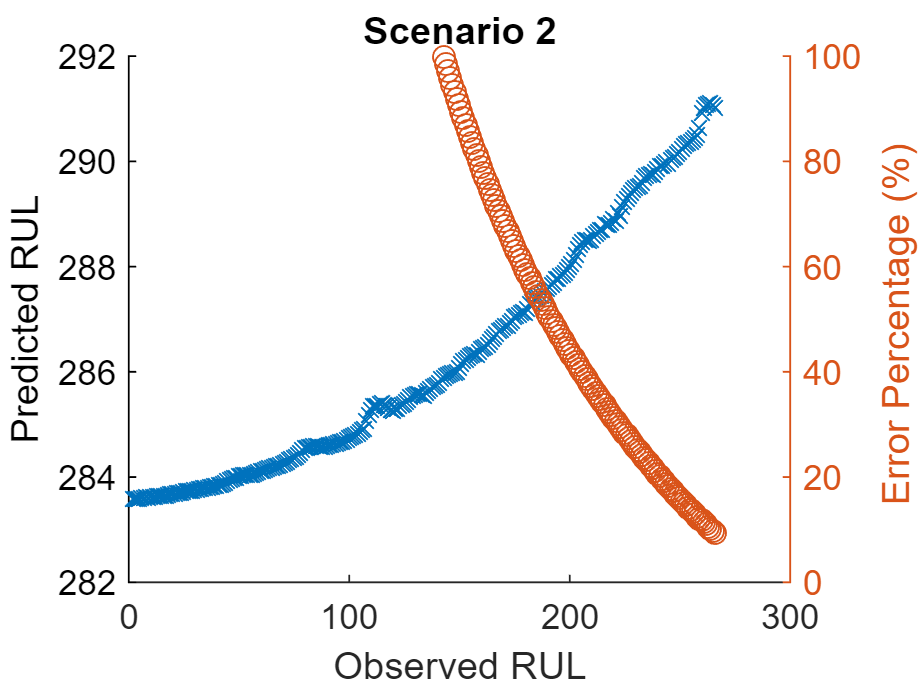

figure
hold on
%plot(Ytrain_future,Ytrain_future)
plot(Ytrain_future,Yhat_future,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage (%) ')
plot(Ytrain_future,diff_percentage_future,'o');
ylim([0 100])

hold off
title 'Scenario 2'

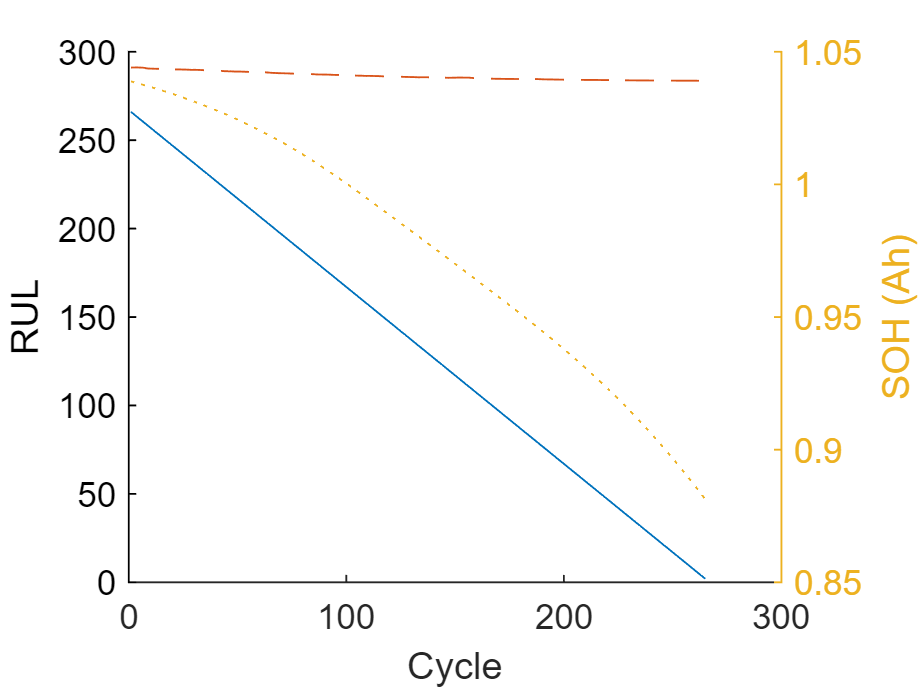


figure, hold on
plot(Ytrain_future)
plot(Yhat_future,'--')
ylabel('RUL')

yyaxis right
ylabel('SOH (Ah)'), xlabel('Cycle')
plot(Ytrain_SOH_future, ':')
hold off

# 클라우드에서 현재까지 학습된 모델로 자신을 예측하면 예측오차가 매우 좀 더 작아지지만, 자신의 데이타로 학습한 만큼의 결과가 나오지 않는다.

load('ryan4_model_RUL.mat', 'mdl_Linear_VdRul_fitrlinregendear')


yhat_all = predict(mdl_Linear_VdRul_fitrlinear,Xtrain_all);
Yhat_all = yhat_all * yrate_RUL + ymin_RUL;

rmse_all = sqrt( mean((Ytrain_all - Yhat_all).^2 ) )

rmse_all = 56.3081

diff_percentage_all = abs(Ytrain_all - Yhat_all)./Ytrain_all.*100

diff_percentage_all = 1.0e+03 *

    0.0434
    0.0421
    0.0416
    0.0408
    0.0403
    0.0404
    0.0402
    0.0404
    0.0397
    0.0392


diff_percentage_avg_all = mean(diff_percentage_all,1)

diff_percentage_avg_all = 32.7476

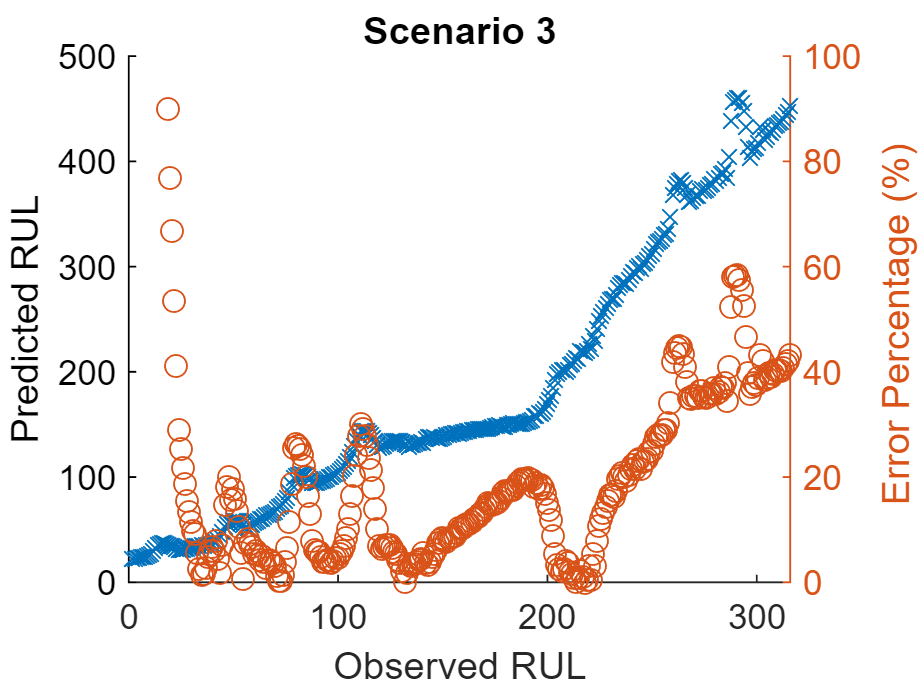

figure
hold on
plot(Ytrain_all,Yhat_all,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage (%) ')
plot(Ytrain_all,diff_percentage_all,'o');
ylim([0 100])

hold off
title 'Scenario 3'

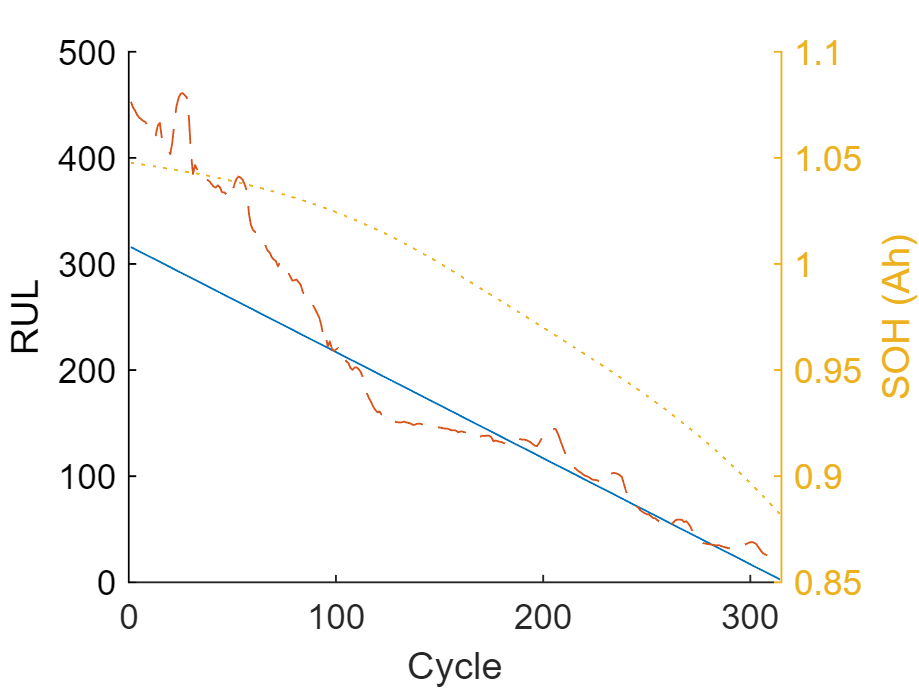



figure, hold on
plot(Ytrain)
plot(Yhat_all,  '--')
ylabel('RUL')

yyaxis right
ylabel('SOH (Ah)'), xlabel('Cycle')
plot(Ytrain_soh,':')
hold off

yhat = predict(mdl_Linear_VdRul_fitrlinear,Xtrain(1,:))

yhat = 0.3864

mdl_Linear_VdRul_fitrlinear.Beta 

ans =    -0.4300
   -0.2471
   -0.0565
    0.0360
    0.1613
    0.3305
    0.4949
    0.5662
    0.4575
    0.2428


mdl_Linear_VdRul_fitrlinear.Bias

ans = -1.0687

yhat_cals = Xtrain(1,:) * mdl_Linear_VdRul_fitrlinear.Beta  +  mdl_Linear_VdRul_fitrlinear.Bias

yhat_cals = 0.3864

## 점진적 학습 - 과거데이타에서 정확한 RUL 안다고 가정하면 러닝레이트를 높이자.


maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);

% Mdl = incrementalRegressionLinear('Epsilon',0.05, ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',1000,'MetricsWindowSize',500, ...
%     'Metrics',{'epsiloninsensitive' 'mse_val' maemetric})

% Mdl = incrementalRegressionLinear(  ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',100,'MetricsWindowSize',50, ...
%     'Learner','leastsquares', ...
%     'Metrics',{ 'mse' })

% 'LearnRate',0.002 => 적응속도가 느리다.
% 'LearnRate',0.1 => 뒤로 갈수록 정확해 진다.
mdl_Linear_VdRul_fitrlinear_inc = incrementalLearner(mdl_Linear_VdRul_fitrlinear, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );
mdl_Linear_VdRul_fitrlinear

mdl_Linear_VdRul_fitrlinear =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
               Lambda: 2.6064e-05
              Learner: 'leastsquares'


  Properties, Methods


mdl_Linear_VdRul_fitrlinear_inc

mdl_Linear_VdRul_fitrlinear_inc =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
              Learner: 'leastsquares'


  Properties, Methods


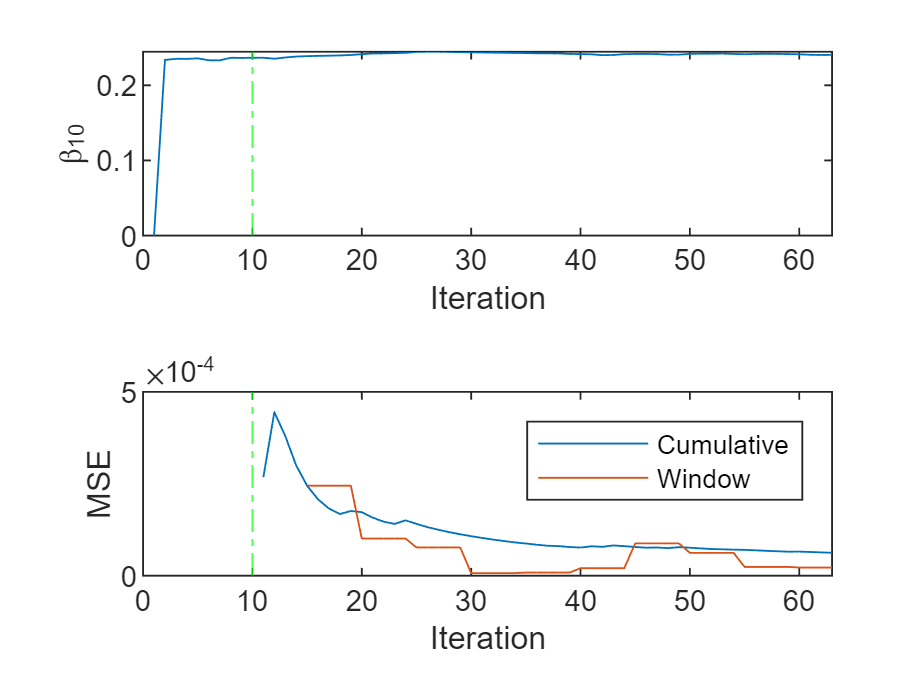

n = numel(ytrain);
% Preallocation
numObsPerChunk = 5; %50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
% mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    
y_predict = []; %zeros();
% Incremental fitting
rng("default"); % For reproducibility
mdl_Linear_VdRul_fitrlinear_inc.Beta' ;    
for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend ;  
    % 문제는 원하는 값을 우리가 알고 있다고 가정하고 다시 Fit을 한다.
    mdl_Linear_VdRul_fitrlinear_inc = updateMetricsAndFit(...
        mdl_Linear_VdRul_fitrlinear_inc,...
        Xtrain(idx,:),...
        ytrain(idx));
    y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear_inc,Xtrain(idx,:));
    mdl_Linear_VdRul_fitrlinear_inc.Beta' ;
    y_predict = [ y_predict ; y_predict_temp ];
    [ytrain(idx) y_predict_temp ytrain(idx)-y_predict_temp] ;
    %ei{j,:} = mdl_Linear_VdRul_fitrlinear_inc.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = mdl_Linear_VdRul_fitrlinear_inc.Metrics{"MeanSquaredError",:};
    %mae{j,:} = mdl_Linear_VdRul_fitrlinear_inc.Metrics{"MeanAbsoluteError",:};
    beta10(j + 1) = mdl_Linear_VdRul_fitrlinear_inc.Beta(10);
end

tiledlayout(2,1)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(mdl_Linear_VdRul_fitrlinear_inc.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
% nexttile
% h = plot(ei.Variables);
% xlim([0 nchunk])
% ylabel('Epsilon Insensitive Loss')
% xline(mdl_Linear_VdRul_fitrlinear_inc.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,ei.Properties.VariableNames)
% xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(mdl_Linear_VdRul_fitrlinear_inc.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')

% nexttile
% h = plot(mae.Variables);
% xlim([0 nchunk])
% ylabel('MAE')
% xline(mdl_Linear_VdRul_fitrlinear_inc.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,mae.Properties.VariableNames)
% xlabel('Iteration')

%yhat_all = predict(mdl_Linear_VdRul_fitrlinear_inc,Xtrain_all);
%y_predict = [ y_predict ; y_predict(end)];

Y_predict = y_predict * yrate_RUL + ymin_RUL;

rmse_all_inc = sqrt( mean((Ytrain_all - Y_predict).^2 ) )

rmse_all_inc = 5.3019

diff_percentage_all_inc = abs(Ytrain_all - Y_predict)./Ytrain_all.*100

diff_percentage_all_inc =     3.2686
    4.6288
    5.2595
    6.2558
    6.8528
    1.5237
    1.2473
    1.3340
    0.4798
    0.1673


diff_percentage_avg_all_inc = mean(diff_percentage_all_inc,1)

diff_percentage_avg_all_inc = 2.6769

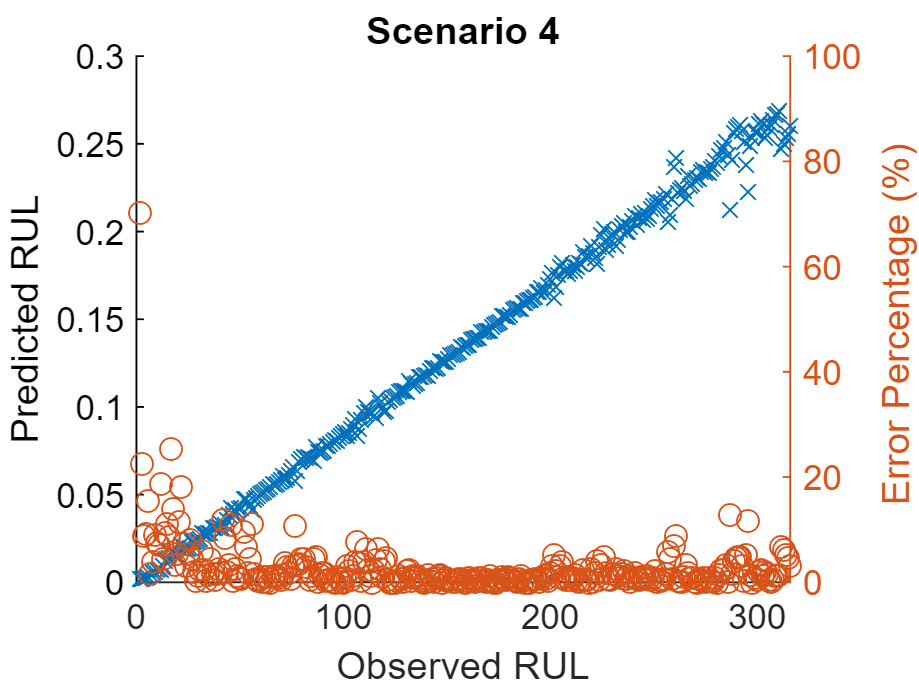

figure
hold on
plot(Ytrain_all,y_predict,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage (%) ')
plot(Ytrain_all,diff_percentage_all_inc,'o');
ylim([0 100])

hold off
title 'Scenario 4'

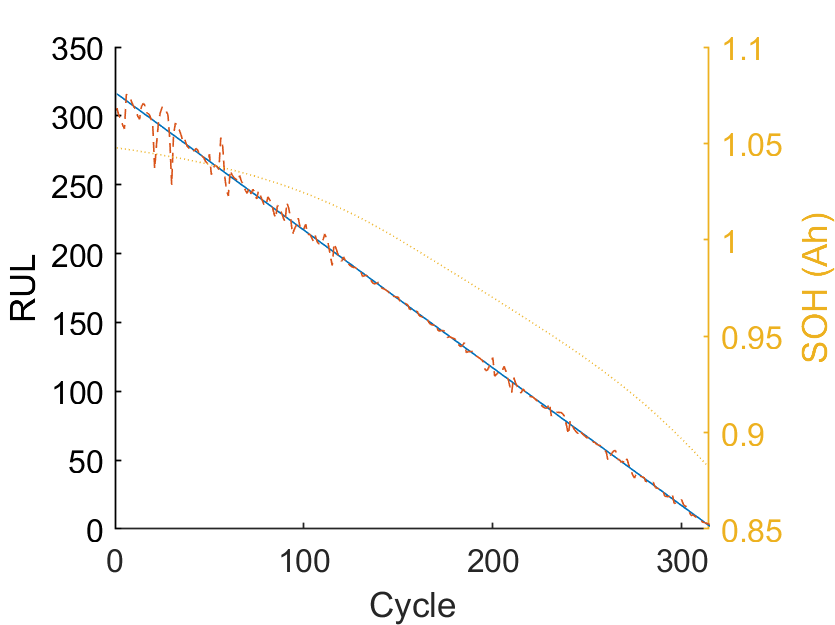


figure, hold on
plot(Ytrain)
plot(Y_predict,'--')
ylabel('RUL')

yyaxis right
ylabel('SOH (Ah)'), xlabel('Cycle')
plot(Ytrain_soh,':')
hold off

## 점진적 학습 - 과거데이타에서 실제로는 정확한 RUL을 얻을 수 없다. 자기가 예측한 값으로 모델 업데이트. 러닝레이트를 줄여야 한다. 0.002


maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);


mdl_Linear_VdRul_fitrlinear_inc1 = incrementalLearner(mdl_Linear_VdRul_fitrlinear, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.002, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );
mdl_Linear_VdRul_fitrlinear

mdl_Linear_VdRul_fitrlinear =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
               Lambda: 2.6064e-05
              Learner: 'leastsquares'


  Properties, Methods


mdl_Linear_VdRul_fitrlinear_inc1

mdl_Linear_VdRul_fitrlinear_inc1 =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
              Learner: 'leastsquares'


  Properties, Methods


n = numel(ytrain);
% Preallocation
numObsPerChunk = 5; %50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
% mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    
y_predict = []; %zeros();
% Incremental fitting
rng("default"); % For reproducibility
mdl_Linear_VdRul_fitrlinear_inc1.Beta' ;

y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear, Xtrain(1:numObsPerChunk,:))

y_predict_temp =     0.3864
    0.3818
    0.3792
    0.3758
    0.3734


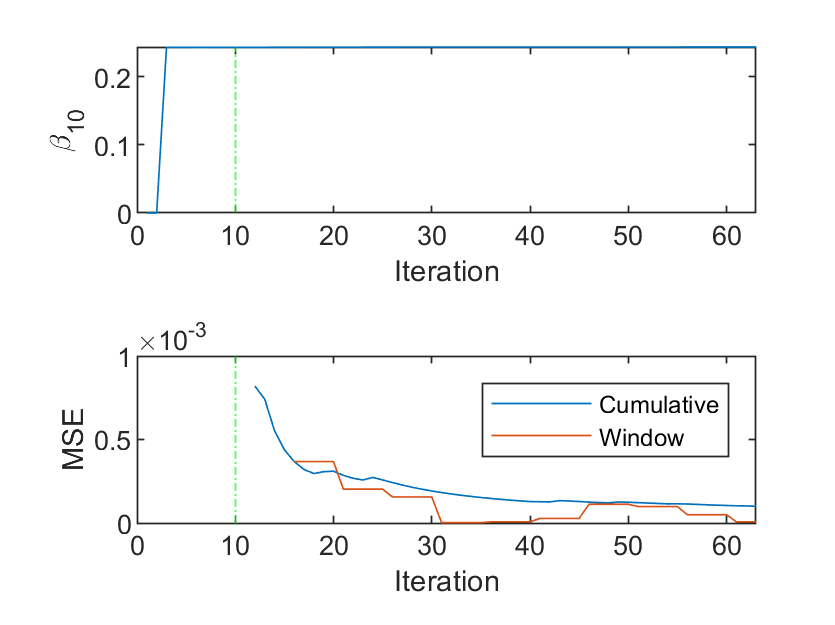

y_predict = y_predict_temp;
for j = 2:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend ;   
    % 문제는 원하는 값을 우리가 알고 있다고 가정하고 다시 Fit을 한다.
    mdl_Linear_VdRul_fitrlinear_inc1 = updateMetricsAndFit( ...
        mdl_Linear_VdRul_fitrlinear_inc1, ...
        Xtrain(idx,:), ...
        y_predict_temp); % 그래나 실제y값을 알기히들다. 
    y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear_inc1,Xtrain(idx,:));
    mdl_Linear_VdRul_fitrlinear_inc1.Beta';
    y_predict = [ y_predict ; y_predict_temp ];
    [ytrain(idx) y_predict_temp ytrain(idx)-y_predict_temp] ;
    %ei{j,:} = mdl_Linear_VdRul_fitrlinear_inc1.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = mdl_Linear_VdRul_fitrlinear_inc1.Metrics{"MeanSquaredError",:};
    %mae{j,:} = mdl_Linear_VdRul_fitrlinear_inc1.Metrics{"MeanAbsoluteError",:};
    beta10(j + 1) = mdl_Linear_VdRul_fitrlinear_inc1.Beta(10);
end

tiledlayout(2,1)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(mdl_Linear_VdRul_fitrlinear_inc1.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
% nexttile
% h = plot(ei.Variables);
% xlim([0 nchunk])
% ylabel('Epsilon Insensitive Loss')
% xline(mdl_Linear_VdRul_fitrlinear_inc1.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,ei.Properties.VariableNames)
% xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(mdl_Linear_VdRul_fitrlinear_inc1.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')

% nexttile
% h = plot(mae.Variables);
% xlim([0 nchunk])
% ylabel('MAE')
% xline(mdl_Linear_VdRul_fitrlinear_inc1.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,mae.Properties.VariableNames)
% xlabel('Iteration')

%yhat_all = predict(mdl_Linear_VdRul_fitrlinear_inc1,Xtrain_all);
%y_predict = [ y_predict ; y_predict(end)];

Y_predict = y_predict * yrate_RUL + ymin_RUL;

rmse_all_inc1 = sqrt( mean((Ytrain_all - Y_predict).^2 ) )

rmse_all_inc1 = 57.1364

diff_percentage_all_inc1 = abs(Ytrain_all - Y_predict)./Ytrain_all.*100

diff_percentage_all_inc1 = 1.0e+03 *

    0.0434
    0.0421
    0.0416
    0.0408
    0.0403
    0.0405
    0.0403
    0.0405
    0.0398
    0.0392


diff_percentage_avg_all_inc1 = mean(diff_percentage_all_inc1,1)

diff_percentage_avg_all_inc1 = 42.0479

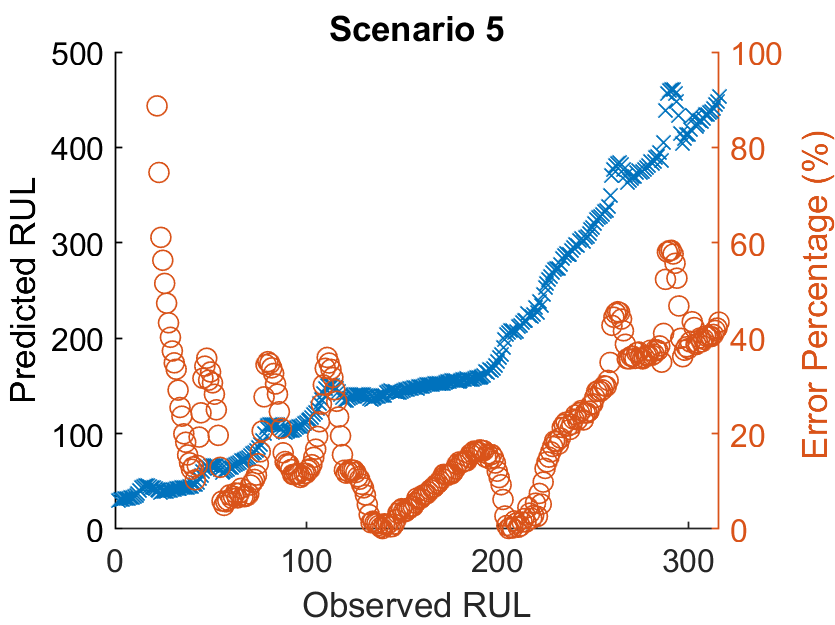

figure
hold on
plot(Ytrain_all,Y_predict,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage (%) ')
plot(Ytrain_all,diff_percentage_all_inc1,'o');
ylim([0 100])

hold off
title 'Scenario 5'

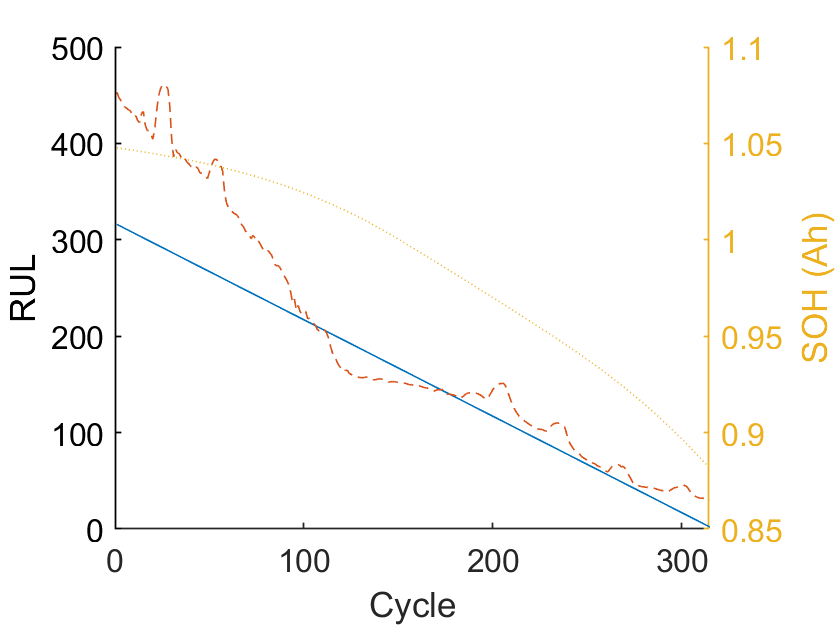


figure, hold on
plot(Ytrain)
plot(Y_predict,'--')
ylabel('RUL')

yyaxis right
ylabel('SOH (Ah)'), xlabel('Cycle')
plot(Ytrain_soh,':')
hold off

## 점진적 학습 - 과거데이타에서 실제로는 정확한 RUL을 얻을 수 없다. 자기가 예측한 값으로 모델 업데이트. 러닝레이트를 0.1로 그대로 유지 


maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);

% Mdl = incrementalRegressionLinear('Epsilon',0.05, ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',1000,'MetricsWindowSize',500, ...
%     'Metrics',{'epsiloninsensitive' 'mse_val' maemetric})

% Mdl = incrementalRegressionLinear(  ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',100,'MetricsWindowSize',50, ...
%     'Learner','leastsquares', ...
%     'Metrics',{ 'mse' })

% 'LearnRate',0.002 => 적응속도가 느리다.
% 'LearnRate',0.1 => 뒤로 갈수록 정확해 진다.
mdl_Linear_VdRul_fitrlinear_inc1a = incrementalLearner(mdl_Linear_VdRul_fitrlinear, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );
mdl_Linear_VdRul_fitrlinear

mdl_Linear_VdRul_fitrlinear =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
               Lambda: 2.6064e-05
              Learner: 'leastsquares'


  Properties, Methods


mdl_Linear_VdRul_fitrlinear_inc1a

mdl_Linear_VdRul_fitrlinear_inc1a =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
              Learner: 'leastsquares'


  Properties, Methods


n = numel(ytrain);
% Preallocation
numObsPerChunk = 5; %50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
% mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    
y_predict = []; %zeros();
% Incremental fitting
rng("default"); % For reproducibility
mdl_Linear_VdRul_fitrlinear_inc1a.Beta' ;

y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear, Xtrain(1:numObsPerChunk,:))

y_predict_temp =     0.3864
    0.3818
    0.3792
    0.3758
    0.3734


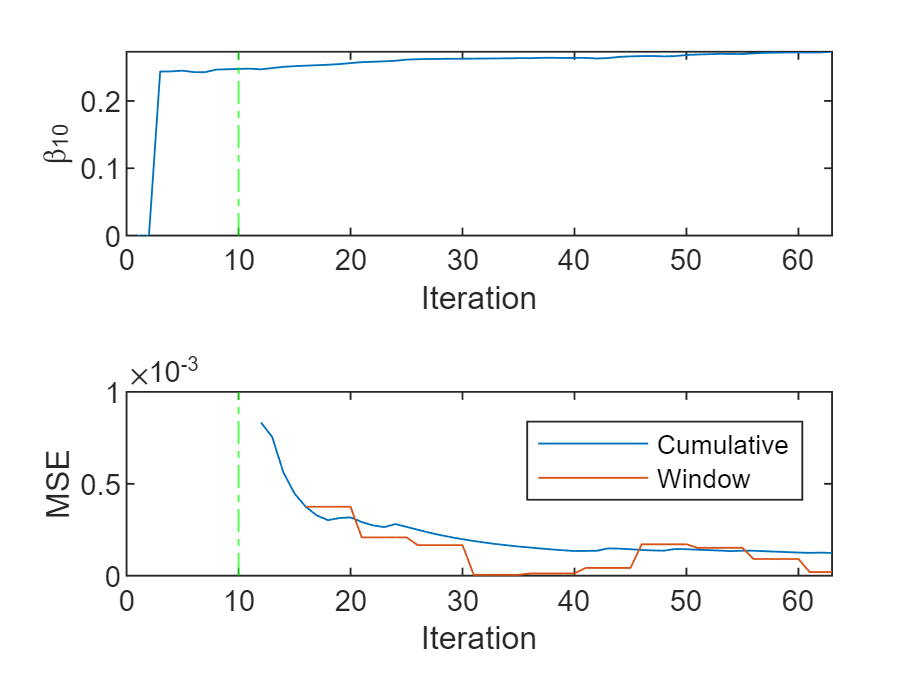

y_predict = y_predict_temp;
for j = 2:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend ;   
    % 문제는 원하는 값을 우리가 알고 있다고 가정하고 다시 Fit을 한다.
    mdl_Linear_VdRul_fitrlinear_inc1a = updateMetricsAndFit( ...
        mdl_Linear_VdRul_fitrlinear_inc1a, ...
        Xtrain(idx,:), ...
        y_predict_temp); % 그래나 실제y값을 알기히들다. 
    y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear_inc1a,Xtrain(idx,:));
    mdl_Linear_VdRul_fitrlinear_inc1a.Beta';
    y_predict = [ y_predict ; y_predict_temp ];
    [ytrain(idx) y_predict_temp ytrain(idx)-y_predict_temp] ;
    %ei{j,:} = mdl_Linear_VdRul_fitrlinear_inc1a.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = mdl_Linear_VdRul_fitrlinear_inc1a.Metrics{"MeanSquaredError",:};
    %mae{j,:} = mdl_Linear_VdRul_fitrlinear_inc1a.Metrics{"MeanAbsoluteError",:};
    beta10(j + 1) = mdl_Linear_VdRul_fitrlinear_inc1a.Beta(10);
end

tiledlayout(2,1)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(mdl_Linear_VdRul_fitrlinear_inc1a.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
% nexttile
% h = plot(ei.Variables);
% xlim([0 nchunk])
% ylabel('Epsilon Insensitive Loss')
% xline(mdl_Linear_VdRul_fitrlinear_inc1a.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,ei.Properties.VariableNames)
% xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(mdl_Linear_VdRul_fitrlinear_inc1a.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')

% nexttile
% h = plot(mae.Variables);
% xlim([0 nchunk])
% ylabel('MAE')
% xline(mdl_Linear_VdRul_fitrlinear_inc1a.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,mae.Properties.VariableNames)
% xlabel('Iteration')

%yhat_all = predict(mdl_Linear_VdRul_fitrlinear_inc1a,Xtrain_all);
%y_predict = [ y_predict ; y_predict(end)];

Y_predict = y_predict * yrate_RUL + ymin_RUL;

rmse_all_inc1a = sqrt( mean((Ytrain_all - Y_predict).^2 ) )

rmse_all_inc1a = 317.0052

diff_percentage_all_inc1a = abs(Ytrain_all - Y_predict)./Ytrain_all.*100

diff_percentage_all_inc1a = 1.0e+04 *

    0.0043
    0.0042
    0.0042
    0.0041
    0.0040
    0.0045
    0.0045
    0.0045
    0.0044
    0.0044


diff_percentage_avg_all_inc1a = mean(diff_percentage_all_inc1a,1)

diff_percentage_avg_all_inc1a = 677.9048

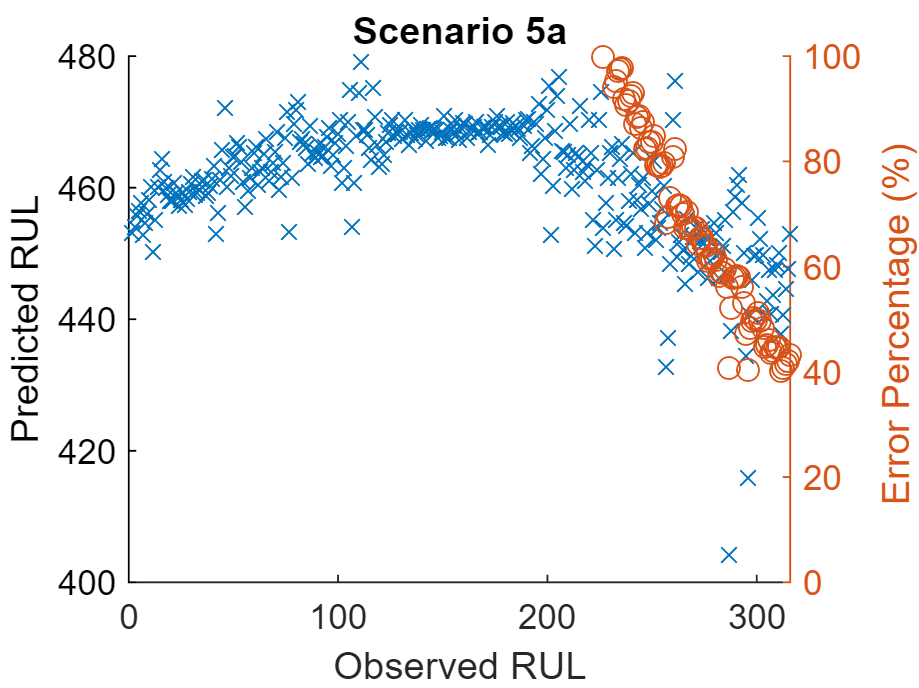

figure
hold on
plot(Ytrain_all,Y_predict,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage (%) ')
plot(Ytrain_all,diff_percentage_all_inc1a,'o');
ylim([0 100])

hold off
title 'Scenario 5a'

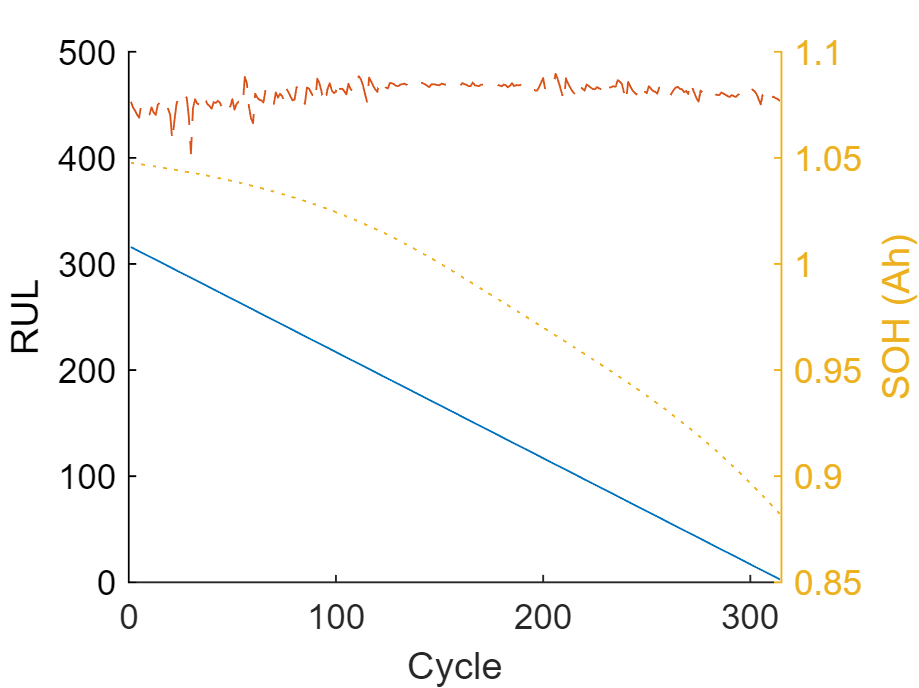


figure, hold on
plot(Ytrain)
plot(Y_predict,'--')
ylabel('RUL')

yyaxis right
ylabel('SOH (Ah)'), xlabel('Cycle')
plot(Ytrain_soh,':')
hold off

## 점진적 학습 - 과거데이타에서 실제로는 정확한 RUL을 얻을 수 없다. 자기가 예측한 값으로 모델 업데이트. 러닝레이트를 0.01로 변경 


maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);

% Mdl = incrementalRegressionLinear('Epsilon',0.05, ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',1000,'MetricsWindowSize',500, ...
%     'Metrics',{'epsiloninsensitive' 'mse_val' maemetric})

% Mdl = incrementalRegressionLinear(  ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',100,'MetricsWindowSize',50, ...
%     'Learner','leastsquares', ...
%     'Metrics',{ 'mse' })

% 'LearnRate',0.002 => 적응속도가 느리다.
% 'LearnRate',0.1 => 뒤로 갈수록 정확해 진다.
mdl_Linear_VdRul_fitrlinear_inc1b = incrementalLearner(mdl_Linear_VdRul_fitrlinear, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.01, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );
mdl_Linear_VdRul_fitrlinear

mdl_Linear_VdRul_fitrlinear =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
               Lambda: 2.6064e-05
              Learner: 'leastsquares'


  Properties, Methods


mdl_Linear_VdRul_fitrlinear_inc1b

mdl_Linear_VdRul_fitrlinear_inc1b =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
              Learner: 'leastsquares'


  Properties, Methods


n = numel(ytrain);


% Preallocation
numObsPerChunk = 5; %50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
% mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    
y_predict = []; %zeros();
% Incremental fitting
rng("default"); % For reproducibility
mdl_Linear_VdRul_fitrlinear_inc1b.Beta' ;

y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear, Xtrain(1:numObsPerChunk,:))

y_predict_temp =     0.3864
    0.3818
    0.3792
    0.3758
    0.3734


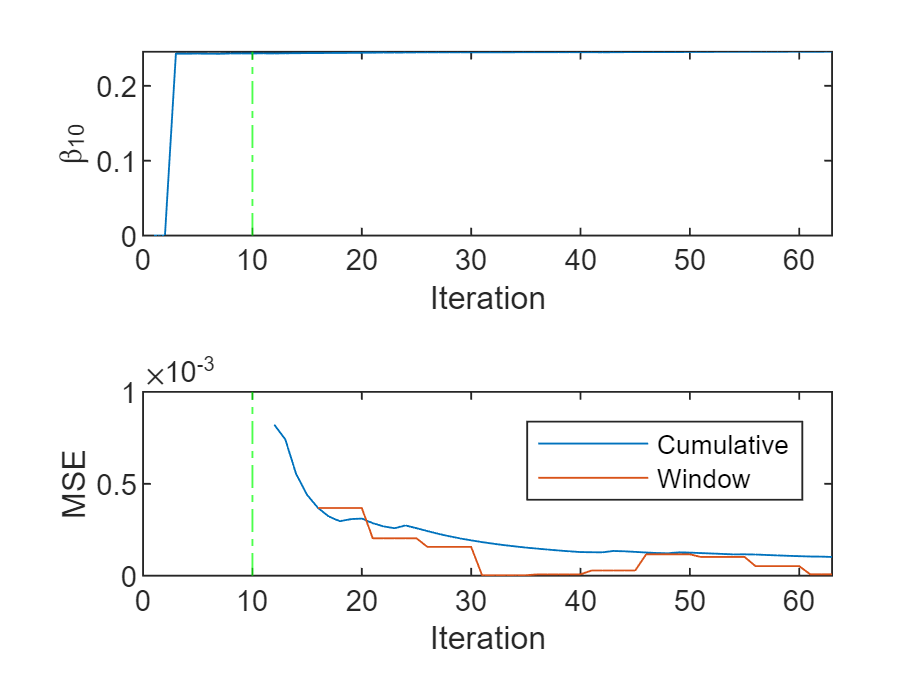

y_predict = y_predict_temp;
for j = 2:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend ;   
    % 문제는 원하는 값을 우리가 알고 있다고 가정하고 다시 Fit을 한다.
    mdl_Linear_VdRul_fitrlinear_inc1b = updateMetricsAndFit( ...
        mdl_Linear_VdRul_fitrlinear_inc1b, ...
        Xtrain(idx,:), ...
        y_predict_temp); % 그래나 실제y값을 알기히들다. 
    y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear_inc1b,Xtrain(idx,:));
    mdl_Linear_VdRul_fitrlinear_inc1b.Beta';
    y_predict = [ y_predict ; y_predict_temp ];
    [ytrain(idx) y_predict_temp ytrain(idx)-y_predict_temp] ;
    %ei{j,:} = mdl_Linear_VdRul_fitrlinear_inc1b.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = mdl_Linear_VdRul_fitrlinear_inc1b.Metrics{"MeanSquaredError",:};
    %mae{j,:} = mdl_Linear_VdRul_fitrlinear_inc1b.Metrics{"MeanAbsoluteError",:};
    beta10(j + 1) = mdl_Linear_VdRul_fitrlinear_inc1b.Beta(10);
end

tiledlayout(2,1)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(mdl_Linear_VdRul_fitrlinear_inc1b.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
% nexttile
% h = plot(ei.Variables);
% xlim([0 nchunk])
% ylabel('Epsilon Insensitive Loss')
% xline(mdl_Linear_VdRul_fitrlinear_inc1b.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,ei.Properties.VariableNames)
% xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(mdl_Linear_VdRul_fitrlinear_inc1b.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')

% nexttile
% h = plot(mae.Variables);
% xlim([0 nchunk])
% ylabel('MAE')
% xline(mdl_Linear_VdRul_fitrlinear_inc1b.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,mae.Properties.VariableNames)
% xlabel('Iteration')

%yhat_all = predict(mdl_Linear_VdRul_fitrlinear_inc1b,Xtrain_all);
%y_predict = [ y_predict ; y_predict(end)];

Y_predict = y_predict * yrate_RUL + ymin_RUL;

rmse_all_inc1b = sqrt( mean((Ytrain_all - Y_predict).^2 ) )

rmse_all_inc1b = 65.7573

diff_percentage_all_inc1b = abs(Ytrain_all - Y_predict)./Ytrain_all.*100

diff_percentage_all_inc1b = 1.0e+03 *

    0.0434
    0.0421
    0.0416
    0.0408
    0.0403
    0.0408
    0.0407
    0.0409
    0.0401
    0.0396


diff_percentage_avg_all_inc1b = mean(diff_percentage_all_inc1,1)

diff_percentage_avg_all_inc1b = 42.0479

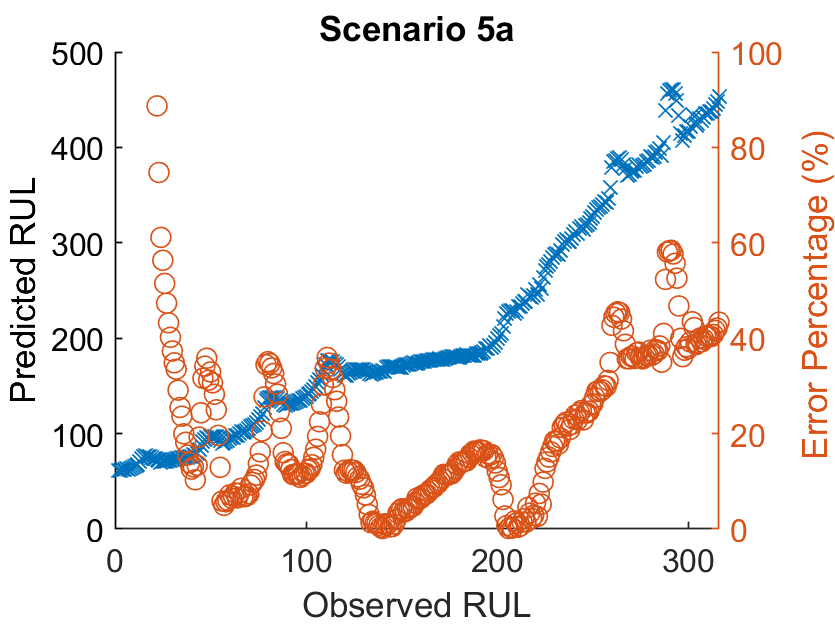

figure
hold on
plot(Ytrain_all,Y_predict,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage (%) ')
plot(Ytrain_all,diff_percentage_all_inc1,'o');
ylim([0 100])

hold off
title 'Scenario 5b'

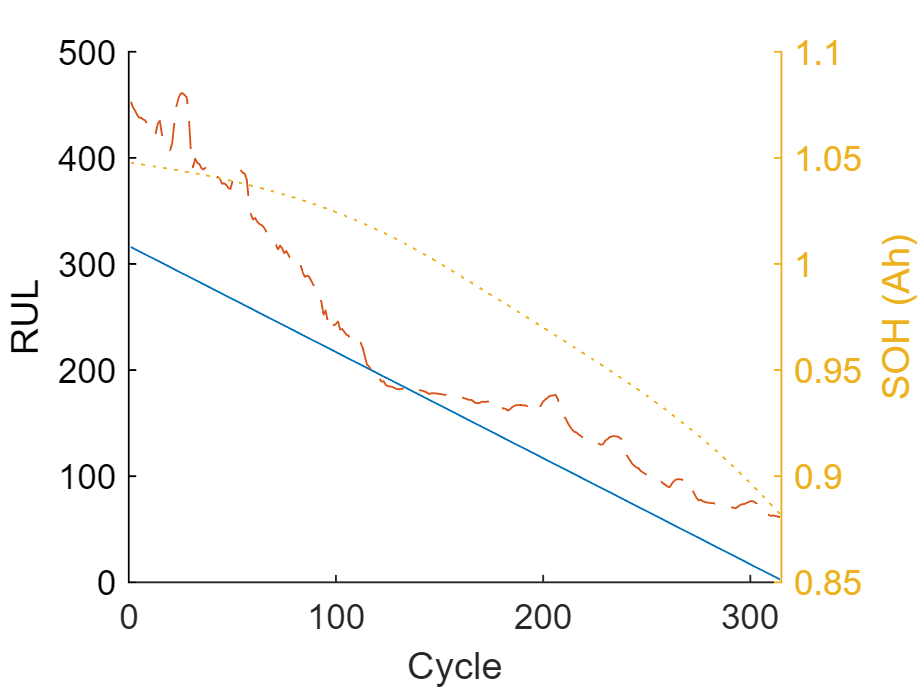


figure, hold on
plot(Ytrain)
plot(Y_predict,'--')
ylabel('RUL')

yyaxis right
ylabel('SOH (Ah)'), xlabel('Cycle')
plot(Ytrain_soh,':')
hold off

## 시나리오 6.




maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);

% Mdl = incrementalRegressionLinear('Epsilon',0.05, ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',1000,'MetricsWindowSize',500, ...
%     'Metrics',{'epsiloninsensitive' 'mse_val' maemetric})

% Mdl = incrementalRegressionLinear(  ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',100,'MetricsWindowSize',50, ...
%     'Learner','leastsquares', ...
%     'Metrics',{ 'mse' })

% 'LearnRate',0.002 => 적응속도가 느리다.
% 'LearnRate',0.1 => 뒤로 갈수록 정확해 진다.
mdl_Linear_VdRul_fitrlinear_inc2 = incrementalLearner(mdl_Linear_VdRul_fitrlinear, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );
mdl_Linear_VdRul_fitrlinear

mdl_Linear_VdRul_fitrlinear =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
               Lambda: 2.6064e-05
              Learner: 'leastsquares'


  Properties, Methods


mdl_Linear_VdRul_fitrlinear_inc2

mdl_Linear_VdRul_fitrlinear_inc2 =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
              Learner: 'leastsquares'


  Properties, Methods


n = numel(ytrain);
% Preallocation
numObsPerChunk = 5; %50;
%y_similar_rul_2nd = ynorm_scenario_7_test_data_2_2ndMatch_RUL;
% size_1 = length(y_similar_rul_2nd)
% size_1_fix = size_1 - rem(size_1, 5);
% 
% n = size_1_fix;
% if n > 250 
%     n = 250;
% end

nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
%mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    
y_predict = []; %zeros();
% Incremental fitting
rng("default"); % For reproducibility
mdl_Linear_VdRul_fitrlinear_inc2.Beta' ;


y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear, Xtrain(1:numObsPerChunk,:))

y_predict_temp =     0.3864
    0.3818
    0.3792
    0.3758
    0.3734


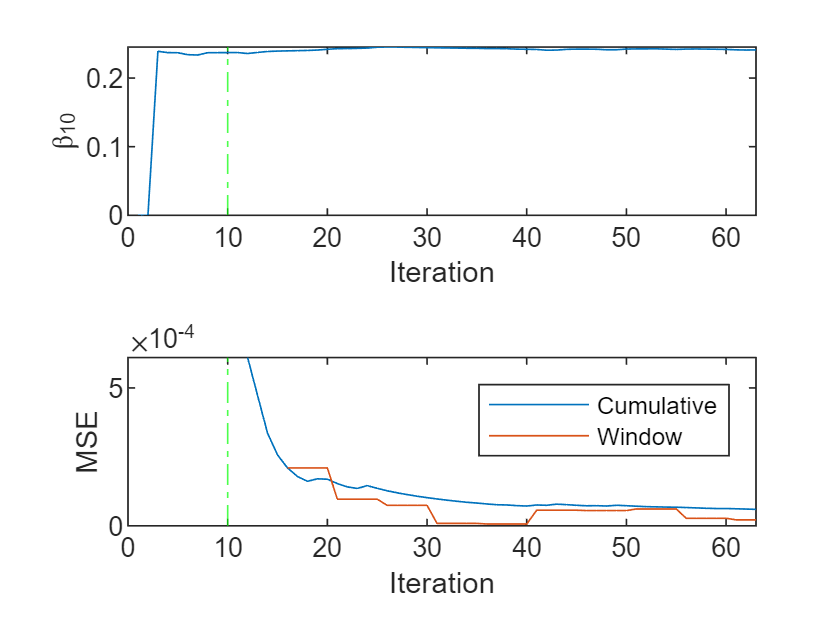

y_predict = y_predict_temp;
for j = 2:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend ; 
    % y_update = ytrain(idx);
    y_update = ( ytrain(idx) + y_predict_temp ) /2 ;

    % 문제는 원하는 값을 우리가 알고 있다고 가정하고 다시 Fit을 한다.
    mdl_Linear_VdRul_fitrlinear_inc2 = updateMetricsAndFit( ...
        mdl_Linear_VdRul_fitrlinear_inc2, ...
        Xtrain(idx,:), ...
        y_update); %  
    y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear_inc2,Xtrain(idx,:));
    mdl_Linear_VdRul_fitrlinear_inc2.Beta';
    y_predict = [ y_predict ; y_predict_temp ];
    [ytrain(idx) y_predict_temp ytrain(idx)-y_predict_temp] ;
    %ei{j,:} = mdl_Linear_VdRul_fitrlinear_inc2.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = mdl_Linear_VdRul_fitrlinear_inc2.Metrics{"MeanSquaredError",:};
    %mae{j,:} = mdl_Linear_VdRul_fitrlinear_inc2.Metrics{"MeanAbsoluteError",:};
    beta10(j + 1) = mdl_Linear_VdRul_fitrlinear_inc2.Beta(10);
end

tiledlayout(2,1)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(mdl_Linear_VdRul_fitrlinear_inc2.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
% nexttile
% h = plot(ei.Variables);
% xlim([0 nchunk])
% ylabel('Epsilon Insensitive Loss')
% xline(mdl_Linear_VdRul_fitrlinear_inc2.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,ei.Properties.VariableNames)
% xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(mdl_Linear_VdRul_fitrlinear_inc2.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')

% nexttile
% h = plot(mae.Variables);
% xlim([0 nchunk])
% ylabel('MAE')
% xline(mdl_Linear_VdRul_fitrlinear_inc2.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,mae.Properties.VariableNames)
% xlabel('Iteration')

%yhat_all = predict(mdl_Linear_VdRul_fitrlinear_inc2,Xtrain_all);
%y_predict = [ y_predict ; y_predict(end)];

Y_predict = y_predict * yrate_RUL + ymin_RUL;

rmse_all_inc2 = sqrt( mean((Ytrain_all - Y_predict).^2 ) )

Arrays have incompatible sizes for this operation.

Related documentation

diff_percentage_all_inc2 = abs(Ytrain_all - Y_predict)./Ytrain_all.*100
diff_percentage_avg_all_inc2 = mean(diff_percentage_all_inc2,1)
figure
hold on
plot(Ytrain_all,Y_predict,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage (%) ')
plot(Ytrain_all,diff_percentage_all_inc2,'o');
ylim([0 100])

hold off
title 'Scenario 6'


figure, hold on
plot(Ytrain)
plot(Y_predict,'--')
ylabel('RUL')

yyaxis right
ylabel('SOH (Ah)'), xlabel('Cycle')
plot(Ytrain_soh,':')
hold off

## 현재까지의 자기 데이타로 학습/예측 - 실제적이지 않다. - 오차 적음


result_pre_summary = table(rmse_pre,diff_percentage_avg_pre);
result_pre_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_pre_summary

result_pre_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    14.091    4.2072


## 현재까지의 자기 데이타로 학습/이후 예측 - 오차 큼


result_future_summary = table(rmse_future,diff_percentage_avg_future);
result_future_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_future_summary

result_future_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    169.43    454.05


## 다른 데이타들로 학습 후 자기 데이타로 예측 - 일반적 시나리오 - 오차 보통


result_all_summary = table(rmse_all,diff_percentage_avg_all);
result_all_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_all_summary

result_all_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    56.308    32.748


## 기본 모델은 클라우드에서 학습한 것. 점진적 학습. 자신의 미래 RUL을 확신하는 경우 - 오차 적음. 학습비율 크게.


result_all_inc_summary = table(rmse_all_inc,diff_percentage_avg_all_inc);
result_all_inc_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_all_inc_summary

result_all_inc_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    5.3019    2.6769


## 확실할 수 없다. 5개의 관측으로 모델갱신 후 다음 5개 예측 - 오차 큼 - 학습비율 작게 


result_all_inc1_summary = table(rmse_all_inc1,diff_percentage_avg_all_inc1);
result_all_inc1_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_all_inc1_summary

result_all_inc1_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    57.136    42.048


## 확실할 수 없다. 5개의 관측으로 모델갱신 후 다음 5개 예측 - 오차 큼 - 학습비율은 그대로 0.1 


result_all_inc1a_summary = table(rmse_all_inc1a,diff_percentage_avg_all_inc1a);
result_all_inc1a_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_all_inc1a_summary

result_all_inc1a_summary = 1×2 table
     RMSE     MAPE 
    ______    _____

    317.01    677.9


## 확실할 수 없다. 5개의 관측으로 모델갱신 후 다음 5개 예측 - 오차 큼 - 학습비율 0.01


result_all_inc1b_summary = table(rmse_all_inc1b,diff_percentage_avg_all_inc1b);
result_all_inc1b_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_all_inc1b_summary

result_all_inc1b_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    65.757    42.048


## 5개의 예측값과 비슷한 다른 데이타의 5개 값을 이용 모델 갱신 -오차 작음


result_all_inc2_summary = table(rmse_all_inc2,diff_percentage_avg_all_inc2);
result_all_inc2_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_all_inc2_summary

result_all_inc2_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    19.953    10.201


% https://kr.mathworks.com/help/matlab/matlab_prog/limitations-of-tables-and-timetables.html

mape_pre       =  diff_percentage_avg_pre        ;
mape_future    =  diff_percentage_avg_future     ;
mape_all       =  diff_percentage_avg_all        ;
mape_all_inc   =  diff_percentage_avg_all_inc    ;
mape_all_inc1  =  diff_percentage_avg_all_inc1   ;
mape_all_inc2  =  diff_percentage_avg_all_inc2   ;

rmse_list = [ rmse_pre ; rmse_future ; rmse_all ; rmse_all_inc ; rmse_all_inc1 ; rmse_all_inc2 ]

rmse_list =    14.0912
  169.4288
   56.3081
    5.3019
   57.1364
   19.9533


mape_list = [ mape_pre ; mape_future ; mape_all ; mape_all_inc ; mape_all_inc1 ; mape_all_inc2 ]

mape_list =     4.2072
  454.0499
   32.7476
    2.6769
   42.0479
   10.2005


scenario_list = ["Scenario 1" ; "Scenario 2" ;"Scenario 3";"Scenario 4";"Scenario 5";"Scenario 6"]

scenario_list = 6×1 string array
    "Scenario 1"
    "Scenario 2"
    "Scenario 3"
    "Scenario 4"
    "Scenario 5"
    "Scenario 6"


scenario_index_list = ["1" ; "2" ;"3";"4";"5";"6"]

scenario_index_list = 6×1 string array
    "1"
    "2"
    "3"
    "4"
    "5"
    "6"


RowNames = {'Scenario 1','Scenario 2','Scenario 3','Scenario 4','Scenario 5','Scenario 6'}

RowNames = 1×6 cell array
    {'Scenario 1'}    {'Scenario 2'}    {'Scenario 3'}    {'Scenario 4'}    {'Scenario 5'}    {'Scenario 6'}


VariableNames = {'Scenario #','RMSE','MAPE'}

VariableNames = 1×3 cell array
    {'Scenario #'}    {'RMSE'}    {'MAPE'}


VariableNames1 = {'RMSE','MAPE'}

VariableNames1 = 1×2 cell array
    {'RMSE'}    {'MAPE'}



result_NoChange = table( scenario_list, rmse_list , mape_list , 'VariableNames',VariableNames);
result_NoChange.Properties.Description = 'Test Result : Without Patten Change';
result_NoChange.Properties

ans =   TableProperties with properties:

             Description: 'Test Result : Without Patten Change'
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Scenario #'  'RMSE'  'MAPE'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


result_NoChange.Properties.RowNames = scenario_list;
result_NoChange

result_NoChange = 6×3 table
                   Scenario #      RMSE      MAPE 
                  ____________    ______    ______

    Scenario 1    "Scenario 1"    14.091    4.2072
    Scenario 2    "Scenario 2"    169.43    454.05
    Scenario 3    "Scenario 3"    56.308    32.748
    Scenario 4    "Scenario 4"    5.3019    2.6769
    Scenario 5    "Scenario 5"    57.136    42.048
    Scenario 6    "Scenario 6"    19.953    10.201



result_NoChange1 = table( rmse_list , mape_list , 'VariableNames',VariableNames1); %,'RowNames',RowNames)
result_NoChange1.Properties.Description = 'Test Result : Without Patten Change';
result_NoChange1.Properties.RowNames = scenario_list

result_NoChange1 = 6×2 table
                   RMSE      MAPE 
                  ______    ______

    Scenario 1    14.091    4.2072
    Scenario 2    169.43    454.05
    Scenario 3    56.308    32.748
    Scenario 4    5.3019    2.6769
    Scenario 5    57.136    42.048
    Scenario 6    19.953    10.201


result_NoChange1.Properties

ans =   TableProperties with properties:

             Description: 'Test Result : Without Patten Change'
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'RMSE'  'MAPE'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {6×1 cell}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


result_NoChange1

result_NoChange1 = 6×2 table
                   RMSE      MAPE 
                  ______    ______

    Scenario 1    14.091    4.2072
    Scenario 2    169.43    454.05
    Scenario 3    56.308    32.748
    Scenario 4    5.3019    2.6769
    Scenario 5    57.136    42.048
    Scenario 6    19.953    10.201


performace_mape = (1 - (mape_all_inc2 / mape_all)) * 100

performace_mape = 68.8510

performace_rmse = (1 - (rmse_all_inc2 / rmse_all)) * 100

performace_rmse = 64.5641

% load patients
% T = table(Gender,Age,Height,Weight,Smoker,Systolic,Diastolic)



% http://matlab.izmiran.ru/help/toolbox/nnet/model211.html


p1 = [-1  0 1 0 1 1 -1  0 -1 1 0 1];
t1 = [-1 -1 1 1 1 2  0 -1 -1 0 1 1 ];
net = linearlayer([0 1],0.1)
[net,y,e,pf] = adapt(net,p1,t1)
%clear mse
mse(e)

net =

    Neural Network
 
              name: 'Linear Neural Layer'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 1
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 0
        sampleTime: 1
 
    connections:
 
       biasConnect: true
      inputConnect: tr

% https://kr.mathworks.com/matlabcentral/answers/269435-what-is-the-difference-between-the-regress-function-and-the-fitlm-function

net =

    Neural Network
 
              name: 'Linear Neural Layer'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 1
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 3
        sampleTime: 1
 
    connections:
 
       biasConnect: true
      inputConnect: tr

y =      0     0     0     0     0     0     0     0     0     0     0     0


e =     -1    -1     1     1     1     2     0    -1    -1     0     1     1


pf =     -1     0     1     0     1     1    -1     0    -1     1     0     1


% The key difference is intercept: 1. "fitlm(x,y)" function uses intercept by default 2. "regress(y,x)" function uses no intercept by default (you can add intercept by adding "ones" matrix)


ans = 1.0833

% https://kr.mathworks.com/help/stats/fitrlinear.html
% fitrlinear
% Fit linear regression model to high-dimensional data


%Alternatives for Lower-Dimensional Data
%High-dimensional linear classification and regression models minimize objective functions relatively quickly, but at the cost of some accuracy, the numeric-only predictor variables restriction, and the model must be linear with respect to the parameters. If your predictor data set is low- through medium-dimensional, or contains heterogeneous variables, then you should use the appropriate classification or regression fitting function. To help you decide which fitting function is appropriate for your low-dimensional data set, use this table.

% Model to Fit	Function	Notable Algorithmic Differences
% SVM	
% Binary classification: fitcsvm
% 
% Multiclass classification: fitcecoc
% 
% Regression: fitrsvm
% 
% Computes the Gram matrix of the predictor variables, which is convenient for nonlinear kernel transformations.
% 
% Solves dual problem using SMO, ISDA, or L1 minimization via quadratic programming using quadprog (Optimization Toolbox).
% 
% Linear regression	
% Least-squares without regularization: fitlm
% 
% Regularized least-squares using a lasso penalty: lasso
% 
% Ridge regression: ridge or lasso
% 
% lasso implements cyclic coordinate descent.
% 
% Logistic regression	
% Logistic regression without regularization: fitglm.
% 
% Regularized logistic regression using a lasso penalty: lassoglm
% 
% fitglm implements iteratively reweighted least squares.
% 
% lassoglm implements cyclic coordinate descent.



% https://kr.mathworks.com/help/stats/incrementalregressionlinear.html
% Description
% incrementalRegressionLinear creates an incrementalRegressionLinear model object, which represents an incremental linear model for regression problems. Supported learners include support vector machine (SVM) and least squares.
% 
% Unlike other Statistics and Machine Learning Toolbox™ model objects, incrementalRegressionLinear can be called directly. Also, you can specify learning options, such as performance metrics configurations, parameter values, and the objective solver, before fitting the model to data. After you create an incrementalRegressionLinear object, it is prepared for incremental learning.
% 
% incrementalRegressionLinear is best suited for incremental learning. For a traditional approach to training an SVM or linear regression model (such as creating a model by fitting it to data, performing cross-validation, tuning hyperparameters, and so on), see fitrsvm or fitrlinear.
% 
% 
% https://kr.mathworks.com/help/stats/regressionlinear-class.html
% Construction
% Create a RegressionLinear object by using fitrlinear.

% codegen common file
gen_code = false

gen_code = logical
   0


load('ryan4_model_RUL.mat', 'mdl_Linear_VdRul_fitrlinear')

cfg = coder.config('lib','ecoder',false);
cfg.GenCodeOnly = true;
cfg.HardwareImplementation.ProdHWDeviceType = 'ARM Compatible->ARM Cortex';


Xtrain_one_sample = Xtrain(1,:)

Xtrain_one_sample =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011



predictorData = coder.typeof(Xtrain(1:5,:)); 
responseData = coder.typeof(ytrain(1:5));
observedData = coder.typeof(ytrain(1:5));



if gen_code
scenario_12_Mdl = Mdl1
%saveLearnerForCoder(scenario_12_Mdl,'scenario_12_Mdl');
saveLearnerForCoder(scenario_12_Mdl,'InitialLinearMdl');

configurer12 = learnerCoderConfigurer(scenario_12_Mdl,Xtrain_one_sample) %,'ObservationsIn','columns')
%configurer12.OutputFileName = 'scenario_12_Mdl'
generateCode(configurer12,cfg,'OutputPath','scenario_12_Mdl')
end

% at first, please delete existing root folder, to delete already generated
%  m files.

if gen_code
mdl_Linear_VdRul_fitrlinear.Beta
scenario_3_Mdl = mdl_Linear_VdRul_fitrlinear
saveLearnerForCoder(scenario_3_Mdl,'InitialLinearMdl');
configurer3 = learnerCoderConfigurer(scenario_3_Mdl,Xtrain_one_sample) %,'ObservationsIn','columns')
generateCode(configurer3,cfg,'OutputPath','scenario_3_Mdl')
end

if gen_code
%load('ryan4_model_RUL.mat', 'mdl_Linear_VdRul_fitrlinear')

scenario_4_Mdl = mdl_Linear_VdRul_fitrlinear_inc
scenario_5_Mdl = mdl_Linear_VdRul_fitrlinear_inc1
scenario_5a_Mdl = mdl_Linear_VdRul_fitrlinear_inc1a
scenario_6_Mdl = mdl_Linear_VdRul_fitrlinear_inc2
end

if gen_code 
 saveLearnerForCoder(scenario_4_Mdl,'scenario_4_Mdl');
 saveLearnerForCoder(scenario_5_Mdl,'scenario_5_Mdl');
 saveLearnerForCoder(scenario_5a_Mdl,'scenario_5a_Mdl');
 saveLearnerForCoder(scenario_6_Mdl,'scenario_6_Mdl');
end
 

% https://kr.mathworks.com/help/stats/classreg.learning.coder.config.svm.classificationsvmcoderconfigurer.generatecode.html
%cfg.CustomFileNameStr = 'sc3';

% configurer4 = learnerCoderConfigurer(scenario_4_Mdl,Xtrain_one_sample) %,'ObservationsIn','columns')
% configurer4.OutputFileName = 'scenario_4_Mdl'
% generateCode(configurer4,cfg,'OutputPath','scenario_4_Mdl')

if gen_code


IncrMdlOutputType = coder.OutputType('myInitialModelIncrLearn');

% change IncrementalMdl to scenario_4_Mdl from myInitialModelIncrLearn.m 
codegen -config cfg  -d scenario_4_Mdl  ...
 myInitialModelIncrLearn ... 
 myUpdateMetricsAndFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myPredictIncrLearn –args {IncrMdlOutputType,predictorData} ...
 -report
end

if gen_code
IncrMdlOutputType = coder.OutputType('myInitialModelIncrLearn');

% change IncrementalMdl to scenario_4_Mdl from myInitialModelIncrLearn.m 
codegen -config cfg  -d scenario_5_Mdl  ...
 myInitialModelIncrLearn ... 
 myUpdateMetricsAndFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myPredictIncrLearn –args {IncrMdlOutputType,predictorData} ...
 -report
end

if gen_code
IncrMdlOutputType = coder.OutputType('myInitialModelIncrLearn');

% change IncrementalMdl to scenario_4_Mdl from myInitialModelIncrLearn.m 
% copy m files to current dir
codegen -config cfg  -d scenario_6_Mdl  ...
 myInitialModelIncrLearn ... 
 myUpdateMetricsAndFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myPredictIncrLearn –args {IncrMdlOutputType,predictorData} ...
 -report
end

거의 다 했다. 

- 된것 

- 매트랩에서 시뮬레이션 한것.

- 안된것 